# Solution of systems of nonlinear equations

Let $f\left(x\right)$ be a vector function $R^n \longrightarrow R^n$  

The Jacobian of $f\left(x\right)$ is the $n\times n$ matrix of first partial derivatives

Both the gradient and Jacobian are "first derivatives"

- gradient: first derivative of a scalar function of several variables 

- Jacobian: first derivative of a vector function of several variables

If $f\left(x\right)$ is a scalar function $R^n \longrightarrow R$, the Jacobian is reduced to a row vector of partial derivatives of $f\left(x\right)$, i.e. the transpose of its gradient.

The Jacobian of the gradient of a scalar function of several variables is the Hessian matrix: "second derivative" of the function in question.

## Primer sistema de ecuaciones


$$x_1^2 +x_1 x_2 =10$$



$$x_2 +3x_1 x_2^2 =57$$


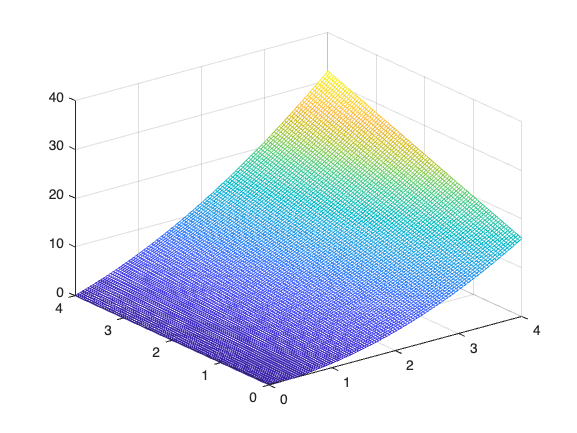

x1= linspace(0,4);
x2 = linspace(0,4);
[X1,X2] = meshgrid(x1,x2);
f1 = X1.^2 + X1.*X2;
mesh(X1,X2,f1);

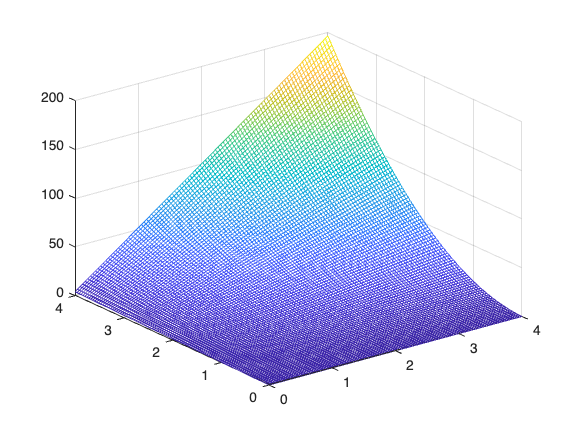

f2 = X2 + 3*X1.*X2.^2;
mesh(X1,X2,f2);

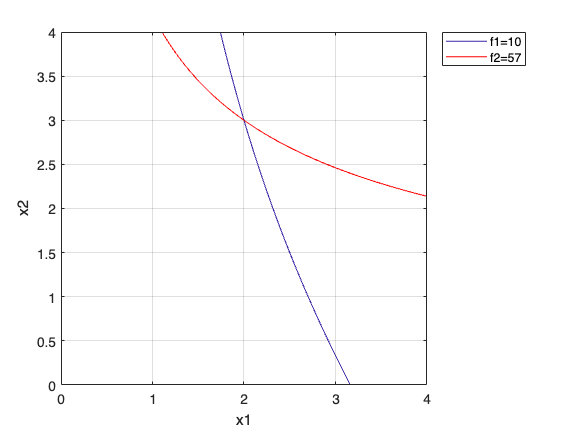

contour(X1, X2, f1,[10 10])
hold on;
contour(X1, X2, f2,[57 57],'r');
grid on;
hold off;
xlabel('x1');
ylabel('x2');
legend('f1=10','f2=57');

f = @(x) [ x(1)^2 + x(1)*x(2) - 10; 
           x(2)+ 3*x(1)*x(2)^2 - 57 ]

f = function_handle with value:
    @(x)[x(1)^2+x(1)*x(2)-10;x(2)+3*x(1)*x(2)^2-57]


J = @(x) [ 2*x(1) + x(2), x(1);
           3*x(2)^2, 1 + 6*x(1)*x(2)]

J = function_handle with value:
    @(x)[2*x(1)+x(2),x(1);3*x(2)^2,1+6*x(1)*x(2)]


x0 = [1; 1];
f(x0)

ans =     -8
   -53


[xr,i] = NewtonRaphsonVV(f,J,x0)

xr =     2.0000
    3.0000


i = 8

f(x)

ans =    -8.3856
  -44.2086


## Segundo sistema de ecuaciones


$$3x_1 -\cos \left(x_2 x_3 \right)=\frac{3}{2}$$



$$4x_1^2 -625x_2^2 +2x_2 =1$$



$$e^{-x_1 x_2 } +20x_3 =-\frac{10\pi -3}{3}$$


f = @(x) [ 3*x(1)-cos(x(2)*x(3))-3/2; 
           4*x(1)^2-625*x(2)^2+2*x(2)-1;
           exp(-(x(1)*x(2)))+20*x(3)+(10*pi-3)/3];
J = @(x) [ 3, sin(x(2)*x(3))*x(3), sin(x(2)*x(3))*x(2);
           8*x(1), -1250*x(2)+2, 0;
           -exp(-(x(1)*x(2)))*x(2), -exp(-(x(1)*x(2)))*x(1), 20];
x0 = [1; 1;1];
[xr,i] = NewtonRaphsonVV(f,J,x0)

xr =     0.8332
    0.0549
   -0.5214


i = 10

## Tercer sistema de ecuaciones


$$2x_1 +x_2 +2x_3^2 \;=\;5$$



$$x_2^3 +4x_3 =4$$



$$x_1 x_2 +x_3 -e^{x_3 } =0$$


f = @(x) [ 2*x(1)+x(2)+2*x(3)^2-5; 
           x(2)^3+4*x(3)-4;
           x(1)*x(2)+x(3)-exp(x(3))];
J = @(x) [ 2, 1, 4*x(3);
           0, 3*x(2)^2, 4;
           x(2), x(1), 1-exp(x(3))];
x0 = [1; 1;1];
[xr,i] = NewtonRaphsonVV(f,J,x0)

xr =     1.4225
    0.9754
    0.7680


i = 6

## Cuarto sistema de ecuaciones

Determine the points of intersection between the circle $x^2 +y^2 =3$ and the hyperbola $\textrm{xy}=1$.

f = @(x) [ x(1)^2+x(2)^2-3; 
           x(1)*x(2)-1];
J = @(x) [ 2*x(1), 2*x(2);
           x(2), x(1)];
x0 = [2; 1];
[xr,i] = NewtonRaphsonVV(f,J,x0)

xr =     1.6180
    0.6180


i = 6

x0 = [1; 2];
[xr,i] = NewtonRaphsonVV(f,J,x0)

xr =     0.6180
    1.6180


i = 6

x0 = [-1; -2];
[xr,i] = NewtonRaphsonVV(f,J,x0)

xr =    -0.6180
   -1.6180


i = 6

x0 = [-2; -1];
[xr,i] = NewtonRaphsonVV(f,J,x0)

xr =    -1.6180
   -0.6180


i = 6

## Problema 12.8 Chapra 4ed

% f = [f1(x,y); f2(x,y)]
% y = -x^2 + x + 0.75
% y + 5*x*y = x^2
% initial guess x=y=1.2
% Sea v=[x;y]   x=v(1), y=v(2)
f = @(v) [v(2)+v(1)^2-v(1)-0.75;
          v(2) + 5*v(1)*v(2) - v(1)^2];
J = @(v) [2*v(1)-1, 1;
          5*v(2)-2*v(1), 1+5*v(1)];
v0=[1.2;1.2];
[v,iter] = NewtonRaphsonVV(f,J,v0)

v =     1.3721
    0.2395


iter = 7

## Problema 12.17 Chapra 4ed

Determine the positive root of

y = x^2 + 1 

y = 2*cos x

Use a graphical approach to obtain your initial guesses

f1= @(x)x^2 + 1 ;
f2=@(x) 2*cos (x);
fplot(f1,[-2 2])

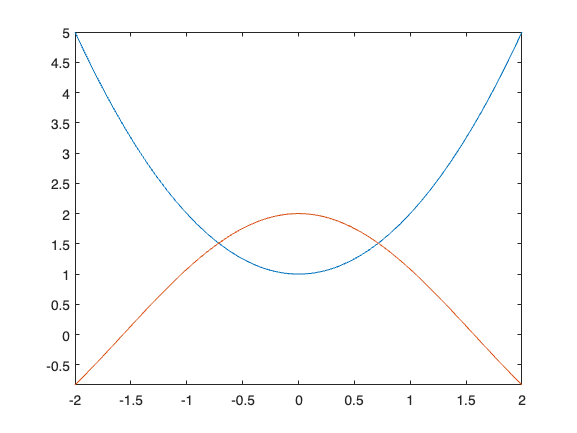

hold on
fplot(f2, [-2 2])

f = @(v) [v(2)-v(1)^2-1;
          v(2)-2*cos(v(1))];
J = @(v) [-2*v(1), 1;
          2*sin(v(1)), 1];
v0=[1;1];
v1=[-1;1];
[v,iter] = NewtonRaphsonVV(f,J,v0)

v =     0.7146
    1.5107


iter = 6

[v,iter] = NewtonRaphsonVV(f,J,v1)

v =    -0.7146
    1.5107


iter = 6

## Jacobiano simbólico

% jacobian(f,v) computes the Jacobian matrix of f with respect to v. 
% The (i,j) element of the result is df(i)/dv(j) (partial derivatives)
syms x1 x2
xs = [x1;x2];
f1 = xs(1)^2 + xs(1)*xs(2) - 10;
f2 = xs(2) + 3*xs(1)*xs(2)^2 - 57;
fs = [f1; f2]

$$fs = \left(\begin{array}{c} {x_{1}}^{2}+x_{2}\,x_{1}-10\\ 3\,x_{1}\,{x_{2}}^{2}+x_{2}-57 \end{array}\right)$$

Js = jacobian(fs,xs)

$$Js = \left(\begin{array}{cc} 2\,x_{1}+x_{2} & x_{1}\\ 3\,{x_{2}}^{2} & 6\,x_{1}\,x_{2}+1 \end{array}\right)$$

f = matlabFunction(fs)      % @(xs1,xs2)

f = function_handle with value:
    @(x1,x2)[x1.*x2+x1.^2-1.0e+1;x2+x1.*x2.^2.*3.0-5.7e+1]


f(1,2)

ans =     -7
   -43


J = matlabFunction(Js)      % @(xs1,xs2) reshapes into a 2x2 matrix

J = function_handle with value:
    @(x1,x2)reshape([x1.*2.0+x2,x2.^2.*3.0,x1,x1.*x2.*6.0+1.0],[2,2])


J(1,2)

ans =      4     1
    12    13


function [xr,i]=NewtonRaphsonVV(f,J,x0)
%Hallar la raíz de la funcion f entre xl y xu. Empleando el método de
%Newton Rapsohd
     MAX = 100;
     tolerancia = eps;
     i = 1;
     cond= true;
     xr=x0-(J(x0)\f(x0));
     
     while cond
         xu=xr;
         xr= xu-(J(xu)\f(xu));
         i=i+1;
         cond=  norm(((xr-xu)/xr),inf)> tolerancia && i < MAX;
     end
     
end

function y=jacobiano(f,x)
    fs=sym(f);
    n=length(fs);
    y=zeros(n,n);
end

function y = centralFirstDerivative(f,x,h)
    h=1;
    i=1;
    n=length(f);
    dfs= diff(fx);
    df=matlabFunction(dfs);
    dfact=df(x);
    
    while i<Max
        der(i)=(f(x+h)-f(x-h))/(2*h);
        i=i+1;
    end
end